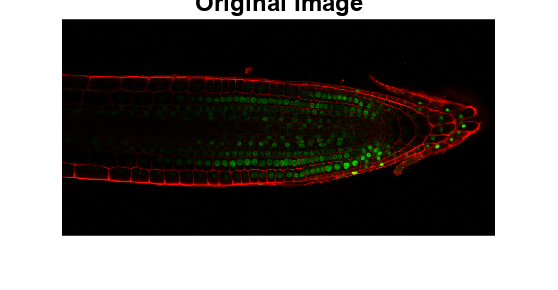

% Load the image
img = imread('StackNinja3.bmp');
imshow(img); title('Original Image');

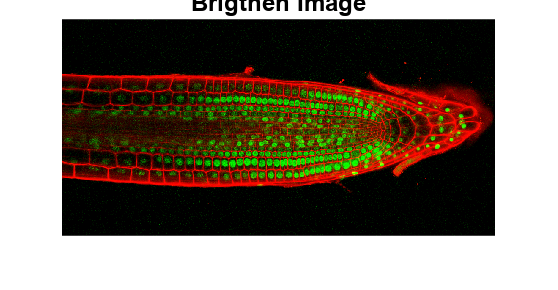


% Brighten img
brigthenimg = imlocalbrighten(img);
figure;
imshow(brigthenimg);title('Brigthen Image');

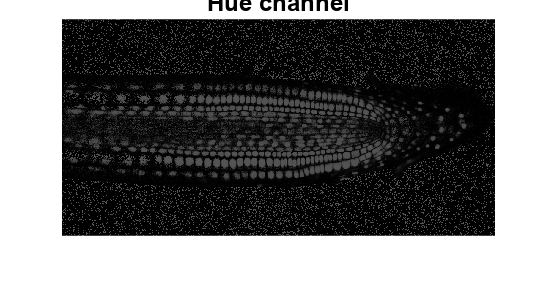


% Convert to HSV
hsv = rgb2hsv(brigthenimg);

% Get the hue channel of the HSV space
hue_channel = hsv(:,:,1);
imshow(hue_channel);title('Hue channel')

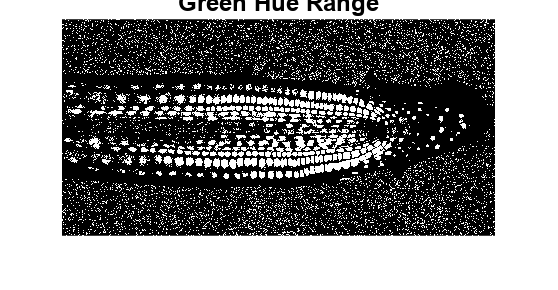



% Set the green range of the Hue channel
green_hue_range = hue_channel >= 0.17 & hue_channel <= 0.5;
imshow(green_hue_range);title('Green Hue Range')

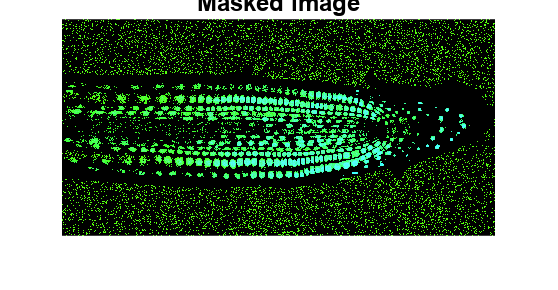


% Repeat the mask to match the size of the original image
green_mask = repmat(green_hue_range,[1,1,3]);

% contrast stretching 
hsv(~green_mask) = hsv(~green_mask) * 1.5;

% % Apply the green mask to the original image
masked_img = bsxfun(@times, hsv, cast(green_mask, 'like', hsv));
imshow(masked_img); title("Masked image")

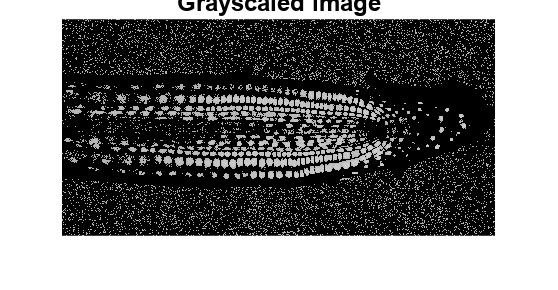


% convert back to rgb 
% gray = hsv2rgb(masked_img);
% imshow(gray); title("hsv to rgb");

% Convert masked image to grayscale
gray_img = rgb2gray(masked_img);
imshow(gray_img); title("Grayscaled image");

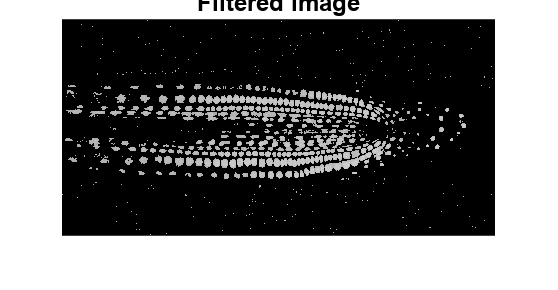


% medfit2
filtered_img = medfilt2(gray_img, [3,3]);
imshow(filtered_img);title("Filtered image")

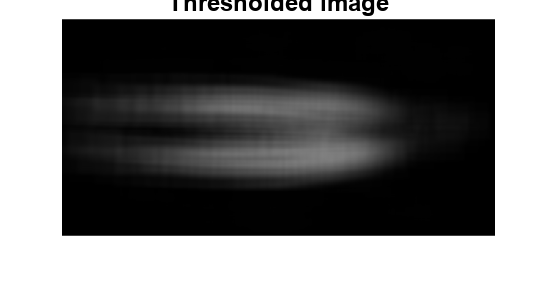



% Apply adaptive threshold to the grayscale image
thres_img = adaptthresh(filtered_img, 0.5);
imshow(thres_img);title("Thresholded image")

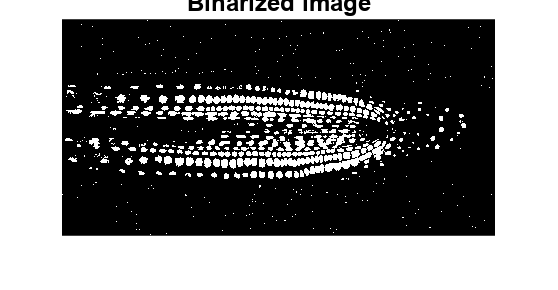


% binarize the img
binary_img = imbinarize(filtered_img, thres_img);
imshow(binary_img);title("Binarized image"); 

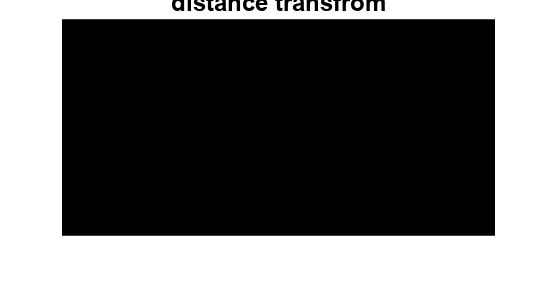



% distance Transform
distance_transform = bwdist(~binary_img);
distance_transform = -distance_transform;
imshow(distance_transform);title('distance transfrom')

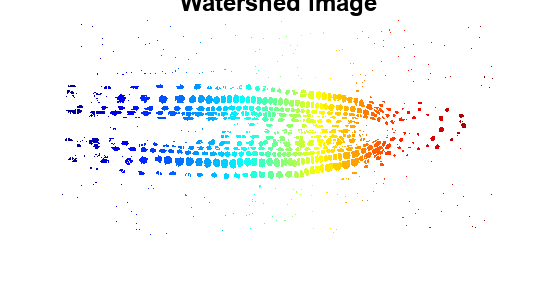


% watershed algorithm
wt= watershed(distance_transform);
wt(~binary_img) = 0;
wtr = label2rgb(wt);
imshow(wtr);title('Watershed image')

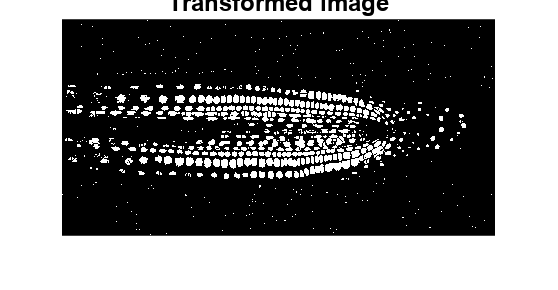



% white background 
gray_scale = rgb2gray(wtr);
white_mask = gray_scale >= 250;
gray_scale(white_mask) = 0;
gray_scale(~white_mask) = 255;
imshow(gray_scale);title('Transformed image')

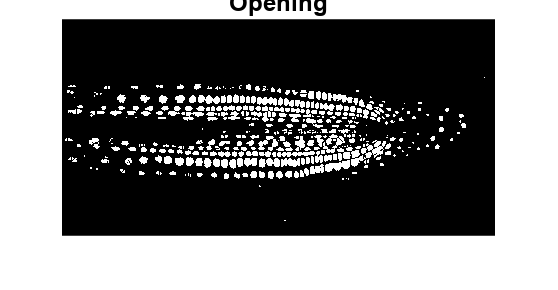


% % Opening 
se = strel('disk',1);
open_img = imopen(gray_scale,se);
imshow(open_img);title('Opening')

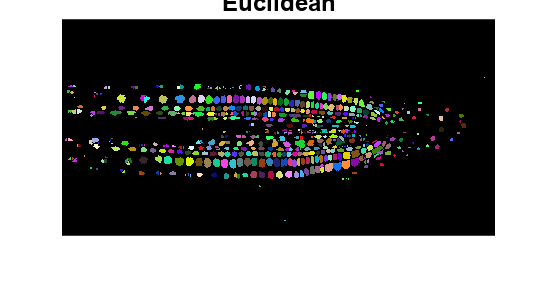


% Label the connected components
cc = bwconncomp(open_img);
num_objects = cc.NumObjects;
    
% Create a color map for the objects
color_map = rand(num_objects, 3);

% Color each object in the image
rgb_img = label2rgb(labelmatrix(cc), color_map, [0, 0, 0]);
   
% Display the image
figure;
imshow(rgb_img);title('Euclidean')


   

% Remove small objects
% binary_img1 = bwareaopen(binary_img, 10);
% imshow(binary_img1);title("open");

% % Apply the green mask to the original image
% masked_img = bsxfun(@times, brigthenimg, cast(green_mask, 'like', brigthenimg));
% imshow(masked_img);
